`BEAM WITH AXIAL FORCE AND METAMATERIAL RESONATORS - RECEPTANCE ANALYSIS`

`Author: M.RM Machado`

`Date: 08/2026`

`Description: This code calculates the receptance (frequency response) of a simply supported beam with axial force (cable), equipped with metamaterial resonators idea. It includes parametric studies on mass ratio and spatial response mapping.`

clear all
close all
clc

%% Case Study - Beam with Axial Force (Ceppel Experiment)
%% Beam Properties
L = 51.95;                      % [m] Length of the beam
eta = 0.01;                     % Structural damping factor
im = sqrt(-1);                  % Imaginary unit

A = pi * (0.02515/2)^2;         % [m^2] Cross-sectional area
I = A^2 / (4 * pi);             % Area moment of inertia
T = 1.680e4;                    % [N] Tensile load
E = 203e9 * (1 + im * eta);     % [Pa] Complex Young's modulus with damping
rho = 3000;                     % [kg/m^3] Density

%% Mode Shape Calculation
n = 1:20;                       % Mode numbers
x = 0:0.5:L;                    % Spatial discretization

% Natural frequencies for simply supported beam with axial force
for jj = 1:length(n)
    wn(jj) = (pi^2 / L^2) * sqrt((E*I) / (rho*A)) * ...
             sqrt(n(jj)^4 + (n(jj)^2 * T * L^2) / (pi^2 * E*I));
    phia(jj,:) = sin(n(jj) * pi * x / L);
end

% Mass-normalized mode shapes
for jj = 1:length(n)
    phi(jj,:) = sqrt(2 / (rho*A)) * sin((n(jj) * pi * x) / L);
end

x = round(length(x) / 1);

%% Frequency Domain Setup
df = 0.01;                      % Frequency resolution
ff = 15;                        % Half sampling frequency [Hz]
fs = 2 * ff;                    % Sampling frequency [Hz]
freq = 5:df:ff;                 % Frequency vector [Hz]
w = freq * 2 * pi;              % Angular frequency vector [rad/s]
Nn = length(w);

tf = 1 / df;                    % Total time
dt = 1 / fs;                    % Time step
t = 0:dt:dt*(2*Nn-1);           % Time vector

%% Bare Beam Receptance
n = length(n);                  % Number of modes
Y = zeros(n, length(w));
Yt = zeros(1, length(w));

for j = 1:n
    for o = 1:length(w)
        Y(j,o) = 1i * w(o) * phi(j, x)^2 / (wn(j)^2 * (1 + eta) - w(o)^2);
    end
    Dmodo(j) = 2 * rho * A * mean(real(Y(j,:))) / pi;
    Yt = Yt + Y(j,:);
end

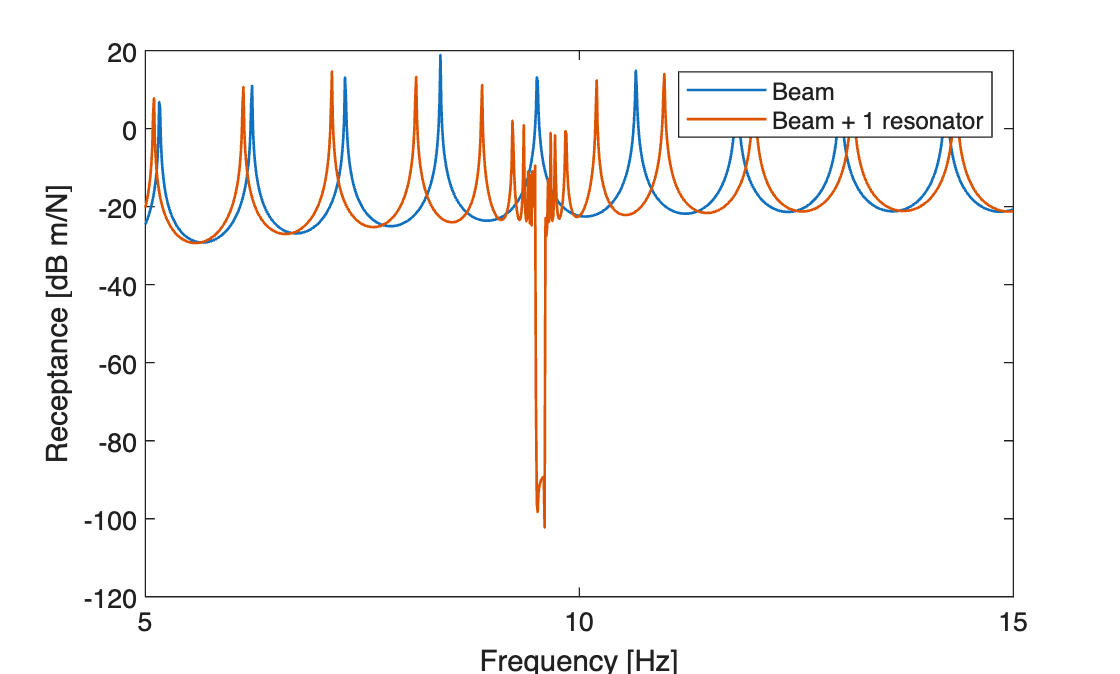

%% Metamaterial Configuration (Assumed Modes)
mu = rho * A * L;               % Total mass of structure [kg]
mp = mu * 0.1;                  % Total mass of all resonators [kg]
S = 10;                         % Number of resonators
deltaL = L / S;                 % Spacing between resonators [m]
eps = mp / (mu * deltaL);       % Mass ratio

wp = 9.514 * pi * 2;            % Resonator natural frequency [rad/s]

% Response and excitation locations
xr = 104;                       % Response coordinate index
xe = 6;                         % Excitation coordinate index

% Initialize receptance matrices
recep_res = zeros(n, length(w));
recep_rest = zeros(1, length(w));
recep_rest_M = zeros(1, length(w));
recep_n = zeros(n, length(w));
recep_nt = zeros(1, length(w));

for j = 1:n
    for o = 1:length(w)
        % Receptance with resonator (1 DOF model)
        recep_res(j,o) = (1i * w(o) * phi(j, xr) * phi(j, xe)) / ...
                         (wn(j)^2 - (w(o)^2) * (1 + (eps * wp^2 / (wp^2 - w(o)^2))));
        
        % Receptance without resonator (bare beam)
        recep_n(j,o) = 1i * w(o) * phi(j, xr) * phi(j, xe) / (wn(j)^2 - w(o)^2);
    end
    recep_rest = recep_rest + recep_res(j,:);
    recep_nt = recep_nt + recep_n(j,:);
end

% Plot comparison: Bare beam vs. beam with resonators
figure;
plot(freq, 20*log10(abs(recep_nt)), freq, 20*log10(abs(recep_rest)), 'linewidth', 1)
legend('Beam', 'Beam + 1 resonator')
xlabel('Frequency [Hz]');
ylabel('Receptance [dB m/N]');

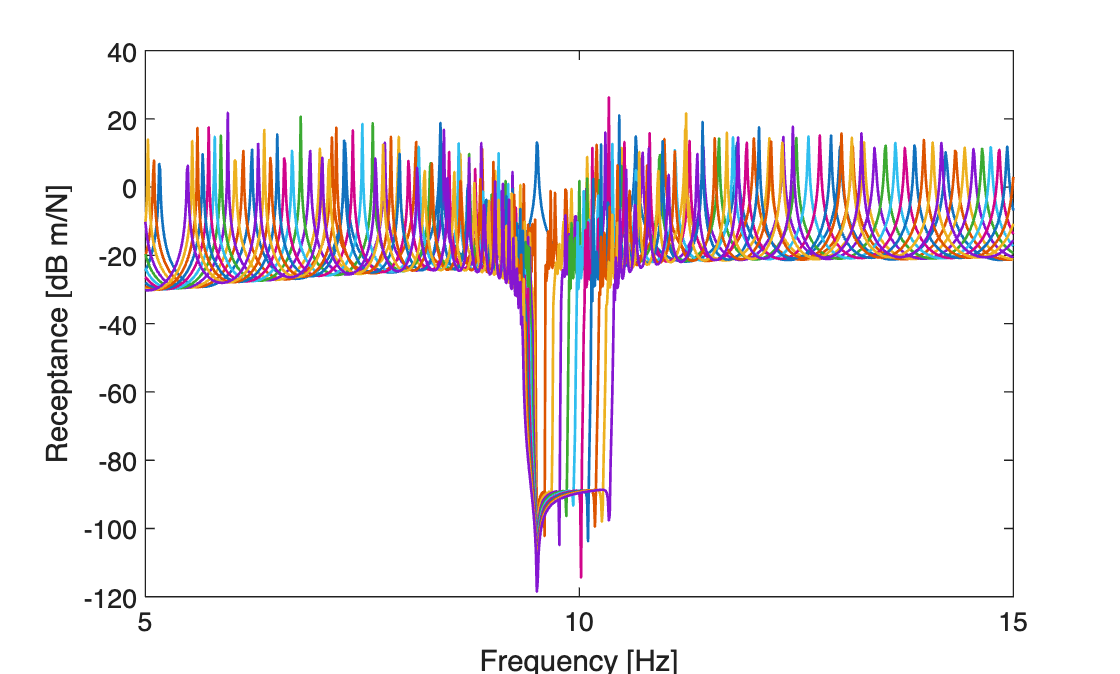

%% Parametric Study: Varying Mass Ratio
% Define response locations for parametric study
xr2 = [104, 104];               % Response coordinate indices (two locations)
xe = 6;                         % Excitation coordinate index
S = 10;                         % Number of resonators
deltaL = L / S;                 % Spacing between resonators [m]
Resp = [];
massr = 0:0.1:1;                % Mass ratio range

for mm = 1:length(massr)
    mp_r = mu * massr(mm);      % Total resonator mass for current ratio
    eps_r = mp_r / (mu * deltaL); % Updated mass ratio
    Uuresp = [];
    
    for kk = 1:2
        recep_resratio = zeros(n, length(w));
        recep_rest_ra = zeros(1, length(w));
        
        for j = 1:n
            for o = 1:length(w)
                % Receptance with resonator for current mass ratio
                recep_resratio(j,o) = (1i * w(o) * phi(j, xr2(kk)) * phi(j, xe)) / ...
                                      (wn(j)^2 - (w(o)^2) * (1 + (eps_r * wp^2 / (wp^2 - w(o)^2))));
            end
            recep_rest_ra = recep_rest_ra + recep_resratio(j,:);
        end
        Uuresp = [Uuresp; recep_rest_ra];
    end
    Resp = [Resp; recep_rest_ra];
end

% Plot receptance for varying mass ratios
figure;
plot(freq, 20*log10(abs(Resp)), 'linewidth', 1)
xlabel('Frequency [Hz]');
ylabel('Receptance [dB m/N]');

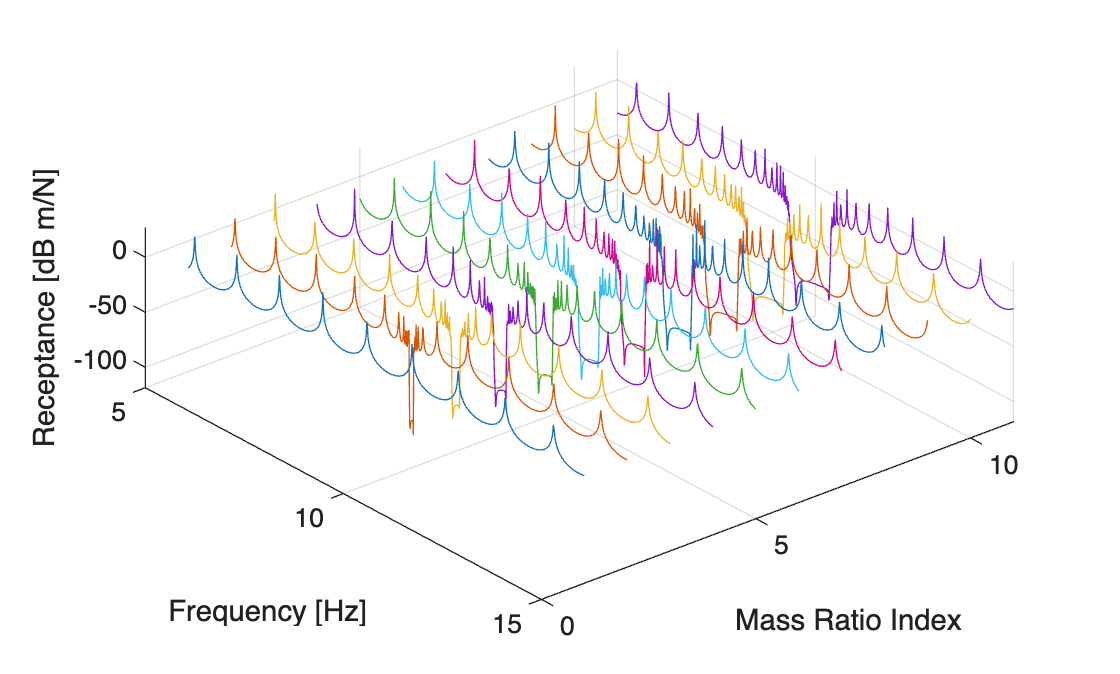


% 3D plot: Receptance vs. Frequency vs. Mass Ratio
figure
modex = size(massr, 2);
xMat = w / (2 * pi);            % Frequency matrix for plotting
yy = 1:1:modex;
yMat = repmat(yy, numel(xMat), 1);
zMat = 20 * log10(abs(Resp));
plot3(xMat, yMat.', zMat);
grid on;
xlabel('Frequency [Hz]');
ylabel('Mass Ratio Index');
zlabel('Receptance [dB m/N]');
view(50, 60);

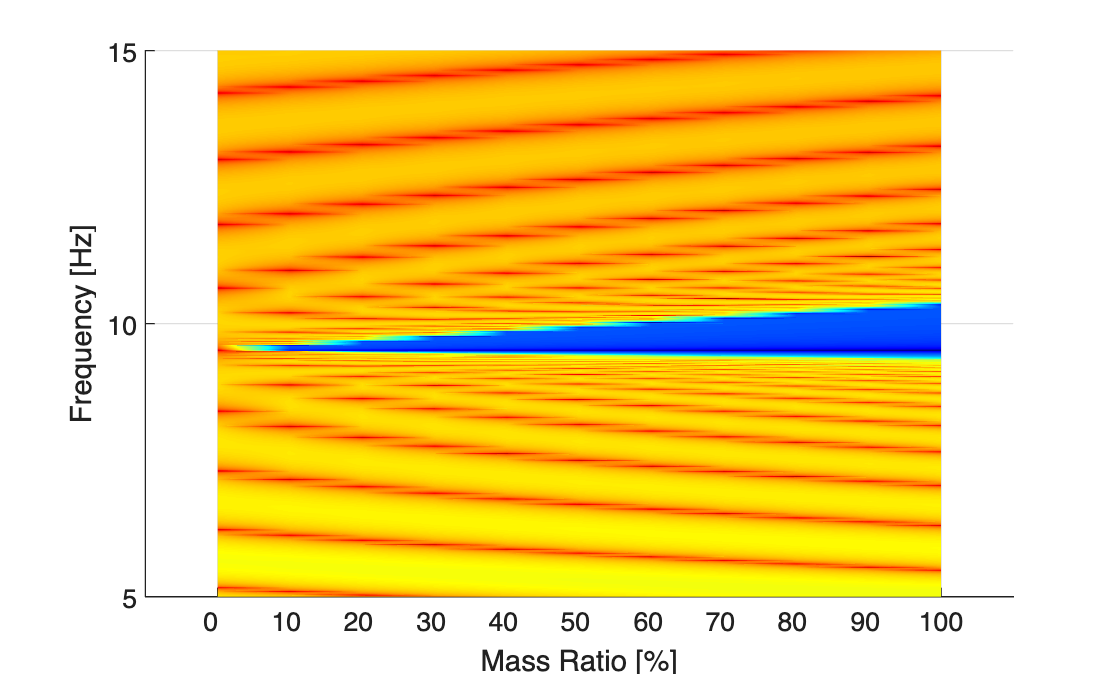


% Surface plot: Receptance map
figure;
colormap('jet');
surf(yMat, xMat, zMat.');
view(0, 90);
shading interp
xlabel('Mass Ratio [%]');
ylabel('Frequency [Hz]');
zlabel('Receptance [dB m/N]');
set(gca, 'XTick', [1 2 3 4 5 6 7 8 9 10 11], ...
         'XTickLabel', [0 10 20 30 40 50 60 70 80 90 100]);

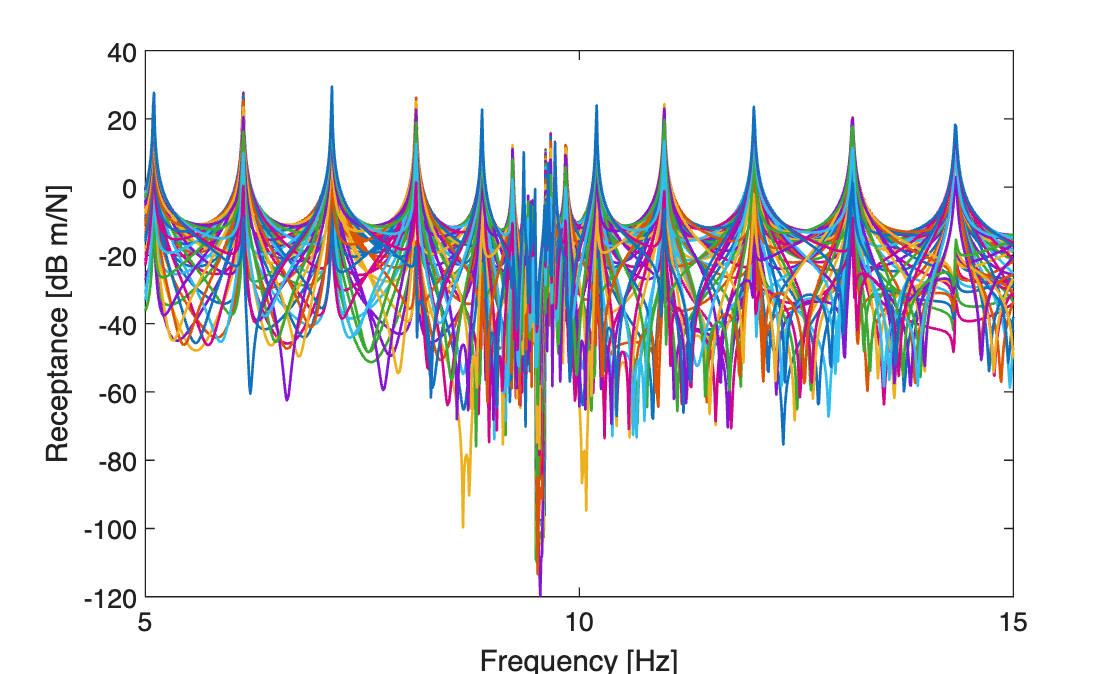


%% Spatial Response Map
xrr = 6:2:104;                  % Response coordinate indices
xe = 104;                       % Excitation coordinate index
Recep_res_all = [];
Recep_all = [];

for k = 1:length(xrr)
    for j = 1:n
        for o = 1:length(w)
            % Receptance with resonator at different response locations
            recep_resd(j,o) = (1i * w(o) * phi(j, xrr(k)) * phi(j, xe)) / ...
                              (wn(j)^2 - (w(o)^2) * (1 + (eps * wp^2 / (wp^2 - w(o)^2))));
            
            % Bare beam receptance at different response locations
            recep_nd(j,o) = 1i * w(o) * phi(j, xrr(k)) * phi(j, xe) / (wn(j)^2 - w(o)^2);
        end
        recep_rest = recep_rest + recep_resd(j,:);
        recep_nt = recep_nt + recep_nd(j,:);
    end
    Recep_res_all = [Recep_res_all; recep_rest];
    Recep_all = [Recep_all; recep_nt];
end

% Plot receptance at different response locations
figure;
plot(freq, 20*log10(abs(Recep_res_all)), 'linewidth', 1)
xlabel('Frequency [Hz]');
ylabel('Receptance [dB m/N]');

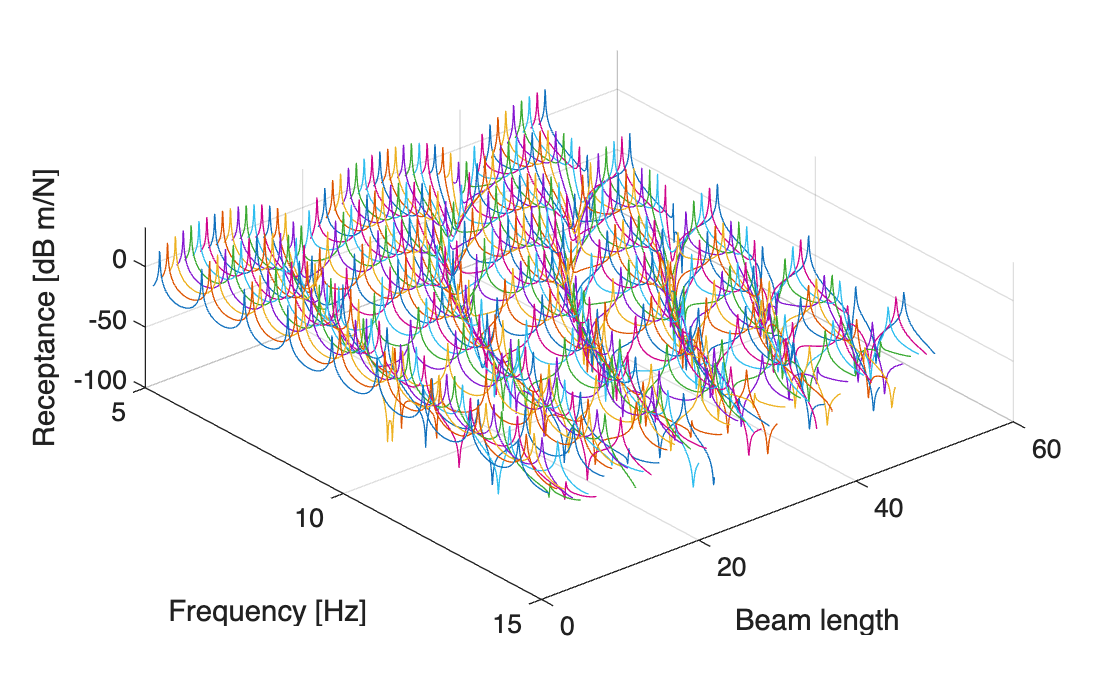


% 3D plot: Receptance vs. Frequency vs. Response Location
figure
modex = size(xrr, 2);
xMat = w / (2 * pi);
yy = 1:1:modex;
yMat = repmat(yy, numel(xMat), 1);
zMat = 20 * log10(abs(Recep_all));
plot3(xMat, yMat, zMat);
grid on;
xlabel('Frequency [Hz]');
ylabel('Beam length');
zlabel('Receptance [dB m/N]');
view(50, 60);

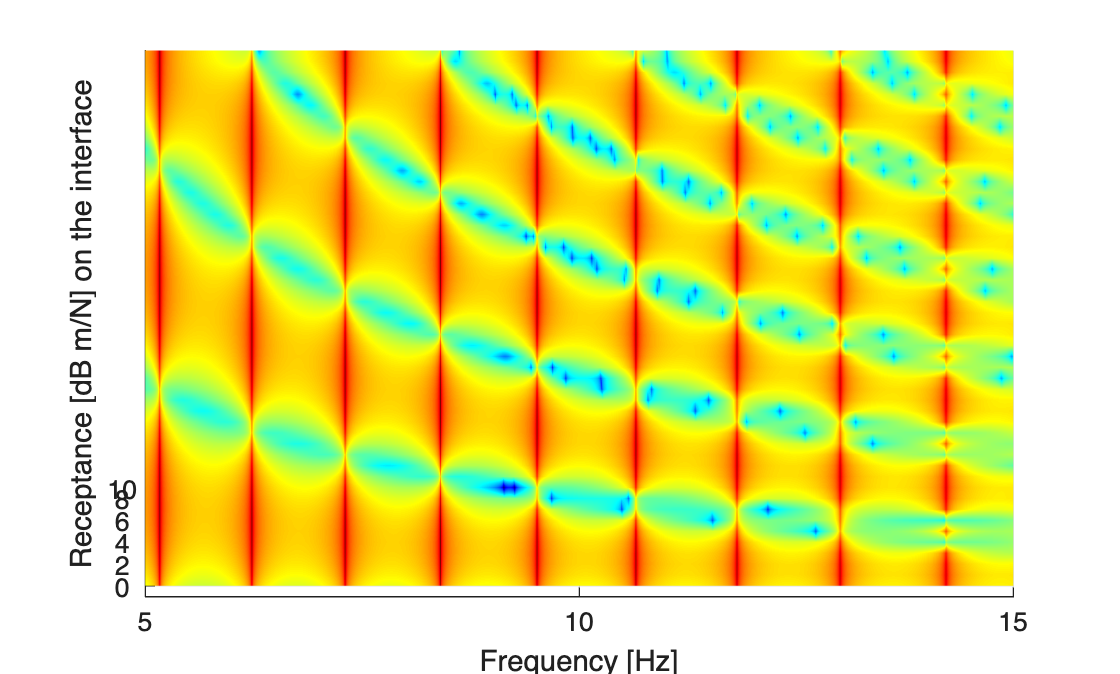


% Surface plot: Receptance map (bare beam)
figure;
colormap('jet');
surf(xMat, yMat.', zMat);
view(0, 90);
shading interp
set(gca, 'YTick', [1 3 5 7 9 10], 'YTickLabel', [0 2 4 6 8 10]);
xlabel('Frequency [Hz]');
ylabel('Receptance [dB m/N] on the interface');
zlabel('Beam length');

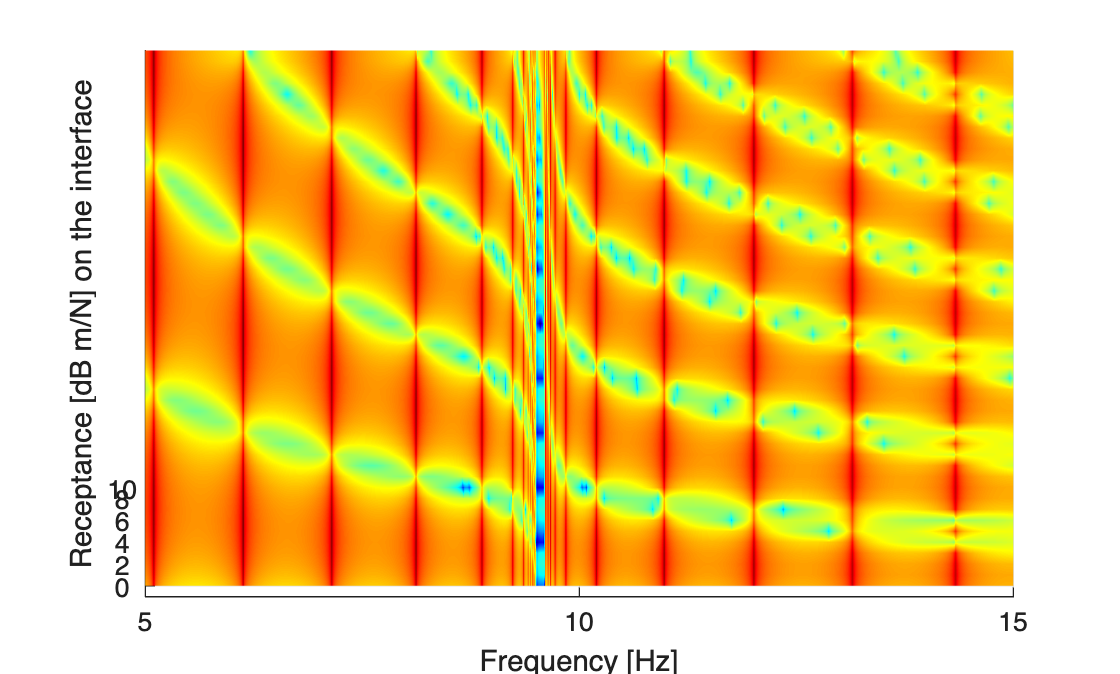


% Surface plot: Receptance map (with resonators)
figure;
colormap('jet');
zMat_res = 20 * log10(abs(Recep_res_all));
surf(xMat, yMat.', zMat_res);
view(0, 90);
shading interp
set(gca, 'YTick', [1 3 5 7 9 10], 'YTickLabel', [0 2 4 6 8 10]);
xlabel('Frequency [Hz]');
ylabel('Receptance [dB m/N] on the interface');
zlabel('Beam length');